## Setup

Clone repo with useful plotting function and add to search path.

!git clone https://github.com/catalystneuro/distributed-coding-matnwb.git
cd ../distributed-coding-matnwb
addpath(genpath(pwd));
cd ..

% path to file, change to desired file
DANDIset_folder = '~/DANDIsets/000017/';
filepath = [DANDIset_folder 'sub-Moniz/sub-Moniz_ses-20170515T120000.nwb'];
% read in file
nwb_file = nwbRead(filepath);
% fetch information about units
unit_info = getUnitInfo(nwb_file);
% display number units
nunits = length(unit_info);
fprintf('Total units: %d\n', nunits)

Total units: 606


% select unit
unit = 461;
% get and display unit info
unit_info = getUnitInfo(nwb_file);

fprintf('Unit recorded from %s\nRecorded with probe %i at depth %.02f \x00b5m \n', ...
    unit_info(unit).area, unit_info(unit).probe, unit_info(unit).depth)

Unit recorded from VISpm
Recorded with probe 2 at depth 3345.20 µm 


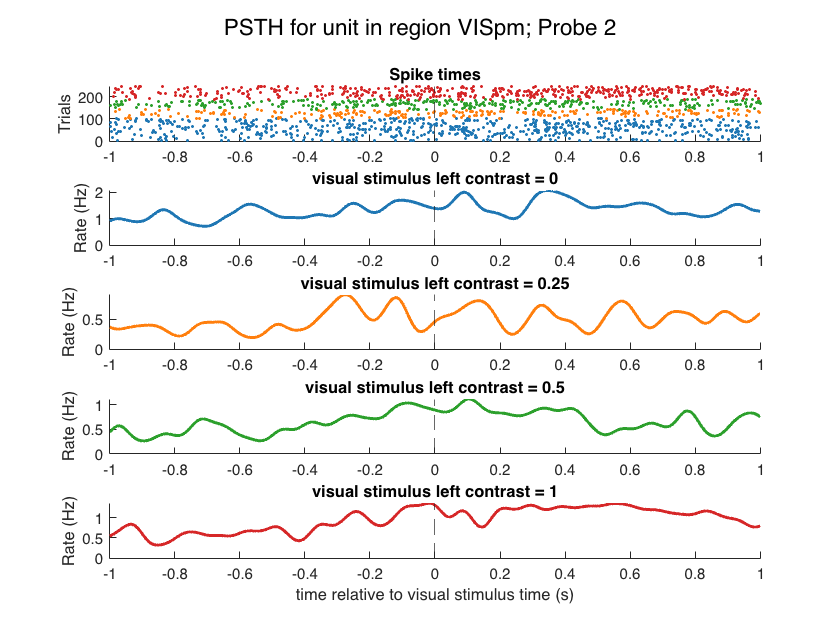

align_to = "visual_stimulus_time";
group_by = "visual_stimulus_left_contrast";
 
psth(...
   nwb_file, ...
   unit_id = unit_info(unit).original_id, ...
   unit_info = unit_info(unit), ...
   align_to = align_to, ...
   group_by = group_by, ...
   before_time = -1, ...
   after_time = 1, ...
   n_bins = 50, ...
   psth_plot_option = 'gaussian', ...
   std = 0.03);